# Documentation - part 2

This Matlab code loads data that was previously extracted and saved to a .mat file in part 1. It creates a scatter plot of the data on a world  map for each of the four variables: sulfur, zinc, mercury, and lead. 

The colormap used is viridis if the corresponding function exists in the  Matlab path, otherwise parula is used. The map is displayed using the worldmap() function. The data is  plotted using scatterm(), with the variable values determining the color of each marker. A colorbar is added to the plot, and its limits are set to the 1st and 99th percentile of the variable values. The world map is overlaid on the plot using geoshow(), with lines instead of filled  polygons. 

Finally, the figure is exported as a PDF file, with the  variable name. This process is  repeated for each of the four variables.

## Load the data extracted during part 1

clearvars;close all; clc;
load('world.mat')
load('moss_data.mat','lat','lon','time','S','Zn','mercury','lead')

% Name variables and their values
var.name = {'Sulfur','Zinc','Mercury','Lead'};
var.val = [S,Zn,mercury,lead];

% marker size for the scatter plot
markersize = 25;

% Colormap choice
if exist('viridis','file'),
    cmap = viridis;
else
    cmap = parula;
end

% loop over each variable
clf;close all
for ii = 1:numel(var.name),

    figure
    % worldmap([58 63],[min(lon)-1,11])
    worldmap([57 75],[min(lon)-1,max(lon)+1])

    scatterm(lat,lon,markersize,var.val(:,ii),'fill')
    c = colorbar;c.Position = [0.76 0.3 0.02 0.5];
    colormap(cmap);
    clim([quantile(var.val(:,ii),0.01),quantile(var.val(:,ii),0.99)])
    hold on
    g = geoshow(world.lat,world.lon,'DisplayType','Line');
    g.Color = [0 0 0];
    set(gcf,'color','w')

    ylabel(c,[var.name{ii},' concentration (mg kg^{-1})'])
    set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

    exportgraphics(gcf,[var.name{ii},'_moss.pdf'],'ContentType','auto')

end


## Show the results as pseudo colormap

Note: I am using the function [bordersm](https://se.mathworks.com/matlabcentral/fileexchange/50390-borders) by Chad Green here

clearvars;close all;

load('moss_data.mat')
x0 = min(lat):0.05:max(lat);
y0 = min(lon):0.05:max(lon);
[x,y] = meshgrid(x0,y0);


F = scatteredInterpolant(lat(~isnan(lead)),lon(~isnan(lead)),lead(~isnan(lead)));

F.ExtrapolationMethod = 'nearest';
F.Method = 'natural';
Z = F(x,y);

if exist('bordersm','file')
[latN,lonN] = bordersm('Norway'); close all;
else
    error(' "bordersm" is available at https://se.mathworks.com/matlabcentral/fileexchange/50390-borders')
end

% Remove data outside the borders of Norway
    land = inpolygon(x(:),y(:),latN,lonN);


% Colormap choice
if exist('viridis','file'),
    cmap = viridis;
else
    cmap = parula;
end

### Plot the pseudo color map

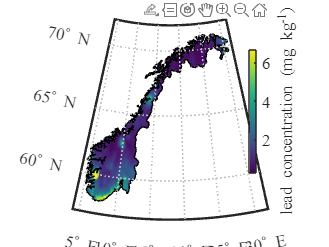

clf;close all
figure
Z1 = reshape(Z,[],1);
Z1(land==0)=nan;
worldmap([min(lat)-1,max(lat)+1],[min(lon)-1,max(lon)+1])
Z1 = reshape(Z1,size(x));
box on
pcolorm(x,y,Z1);
g = geoshow(latN,lonN,'DisplayType','Line');
g.Color = [0 0 0];
set(gcf,'color','w')
c = colorbar;c.Position = [0.76 0.3 0.02 0.5];
colormap(cmap);
clim([quantile(Z(:),0.01),quantile(Z(:),0.99)])
ylabel(c,['lead concentration (mg kg^{-1})'])
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')